%  artificial data from previous exercise
clear;
rng('default');

mu1 = [0.4; 0.6]; sd1 = [0.9; 0.7];
mu2 = [2.5; 3.0]; sd2 = [0.9; 0.7];
%training and test set
X_train_c1 = randn(2, 1000) .* sd1 + mu1;
X_train_c2 = randn(2,  800) .* sd2 + mu2;
X_train = [X_train_c1, X_train_c2];
Y_train = [ones(1,1000), -ones(1,800)];

X_test_c1 = randn(2, 500) .* sd1 + mu1;
X_test_c2 = randn(2, 400) .* sd2 + mu2;
X_test = [X_test_c1, X_test_c2];
Y_test = [ones(1,500), -ones(1,400)];
X_all = [X_train, X_test];   % 2 x 2700
Y_all = [Y_train, Y_test];   % 1 x 2700

% Crossvalidation 10 fold 10
num_repetitions = 10;
num_folds       = 10;
all_accuracies  = zeros(num_repetitions, num_folds);

for rep = 1:num_repetitions
    indices = crossvalind('Kfold', Y_all, num_folds);
    for fold = 1:num_folds
        test_idx  = (indices == fold);
        train_idx = ~test_idx;

        [~, fold_acc, ~, ~, ~] = custom_LDA( ...
            X_all(:,train_idx), Y_all(train_idx), ...
            X_all(:,test_idx),  Y_all(test_idx));

        all_accuracies(rep, fold) = fold_acc;
    end
end

Test Set Accuracy: 98.15%
Train Set Accuracy: 97.86%
Test Set Accuracy: 97.78%
Train Set Accuracy: 97.90%
Test Set Accuracy: 97.78%
Train Set Accuracy: 97.94%
Test Set Accuracy: 98.89%
Train Set Accuracy: 97.78%
Test Set Accuracy: 98.89%
Train Set Accuracy: 97.78%
Test Set Accuracy: 97.41%
Train Set Accuracy: 97.98%
Test Set Accuracy: 97.04%
Train Set Accuracy: 97.98%
Test Set Accuracy: 97.04%
Train Set Accuracy: 97.90%
Test Set Accuracy: 97.04%
Train Set Accuracy: 97.98%
Test Set Accuracy: 98.89%
Train Set Accuracy: 97.78%
Test Set Accuracy: 97.04%
Train Set Accuracy: 97.98%
Test Set Accuracy: 98.15%
Train Set Accuracy: 97.86%
Test Set Accuracy: 97.78%
Train Set Accuracy: 97.90%
Test Set Accuracy: 99.63%
Train Set Accuracy: 97.74%
Test Set Accuracy: 96.67%
Train Set Accuracy: 98.02%
Test Set Accuracy: 98.52%
Train Set Accuracy: 97.82%
Test Set Accuracy: 96.67%
Train Set Accuracy: 98.07%
Test Set Accuracy: 98.52%
Train Set Accuracy: 97.82%
Test Set Accuracy: 97.78%
Train Set Accuracy: 


mean_cv = mean(all_accuracies(:));
std_cv  = std(all_accuracies(:));

fprintf('Artificial Data 10x10-fold CV Results\n');

Artificial Data 10x10-fold CV Results


fprintf('Mean CV Accuracy : %.2f%%\n', mean_cv * 100);

Mean CV Accuracy : 97.90%


fprintf('Std  CV Accuracy : %.2f%%\n', std_cv  * 100);

Std  CV Accuracy : 0.78%


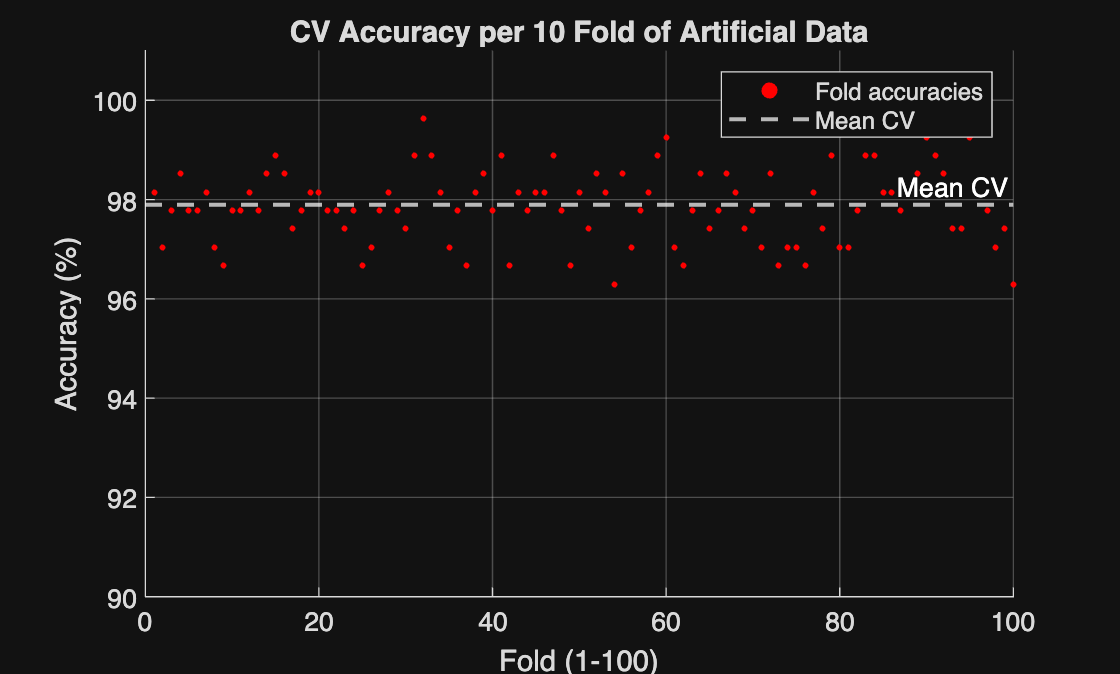


figure;
scatter(1:100, all_accuracies(:)' * 100, 5, 'red', 'filled');
yline(mean_cv * 100, '--', 'LineWidth', 1.5, 'Color', 'white', 'Label', 'Mean CV');
title('CV Accuracy per 10 Fold of Artificial Data');
xlabel('Fold (1-100)');
ylabel('Accuracy (%)');
ylim([90 101]);
grid on;
legend('Fold accuracies', 'Mean CV');